# Sum of random variables drawn from Gaussian distributions

We have two random variables drawn from gaussian distributions:


$$g_1 \sim \mathcal{N}(\mu_1,\,\sigma_1^2) \quad
g_2 \sim \mathcal{N}(\mu_2,\,\sigma_2^2)$$


clear variables; close all; clc;
addpath utilities\

% Define the gaussian distributions of g1 and g2 by their parameters
mu1 = 5;
sigma1 = 1;
mu2 = 10;
sigma2 = 3;

The sum of two random variables drawn from gaussian distributions is a random variable drawn from a gaussian distribution with the following properties:


$$g_1+g_2=g \sim \mathcal{N}(\mu,\,\sigma^2)$$


where:


$$\mu=\mu_1+\mu_2\\
\sigma^2 = \sigma_1^2 + \sigma_2^2
$$


% Define the gaussian distributions of g by its parameters
mu = mu1+mu2;
sigma = sqrt(sigma1^2+sigma2^2);

Compute the Probability Density Functions:

% define x vector over calculating the pdfs
xstart = min([mu1 mu2 mu])-5*max([sigma1 sigma2 sigma]);
xend = max([mu1 mu2 mu])+5*max([sigma1 sigma2 sigma]);
deltax = 1e-4;
x = xstart:deltax:xend;
% pdfs
pdf1 = normpdf(x,mu1,sigma1);
pdf2 = normpdf(x,mu2,sigma2);
pdf = normpdf(x,mu,sigma);

Probability Density Functions with continous sample spaces and Probability Mass Functions with discrete sample spaces follow:


$$\int_{x \in \mathcal{X}} f(x)dx =1 \quad \sum_\mathcal{X} f(x)\Delta x =1$$


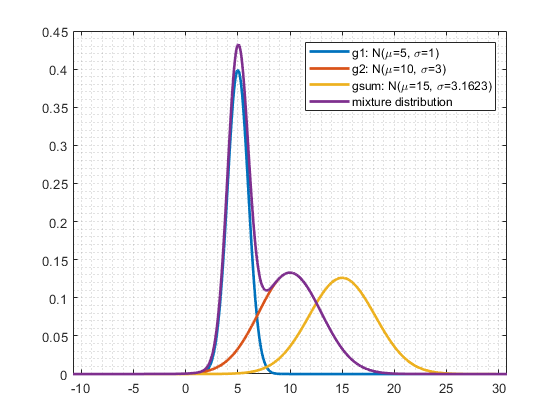

% check
% sum(g)*dx; trapz(g,x);

% mixture distribution
mg = pdf1+pdf2;

% plot
figure
plot_gaussian_pdf(x,pdf1,mu1,sigma1,'g1: ')
hold on; grid minor;
plot_gaussian_pdf(x,pdf2,mu2,sigma2,'g2: ')
plot_gaussian_pdf(x,pdf,mu,sigma,'gsum: ')
plot(x,mg,'LineWidth',2,'DisplayName','mixture distribution')
legend
xlim([xstart xend])